clear all
close all

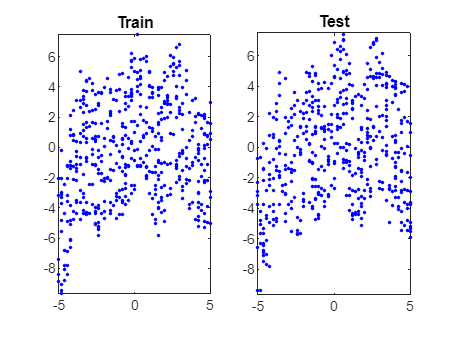

N = 500;
f = @(x) 1 + x/4 - (x.^2)./8 + sin(3*x) + cos(2*x);
xmin = -5; xmax = 5;

num_points = 50;
delta = (xmax - xmin)/num_points;
%xs = linspace(xmin, xmax, N)' + (rand([N 1]) - 0.5)*delta;

xs = randi([0 num_points], [N,1])*delta + xmin;
ys = f(xs) + (rand([N 1]) - 0.5)*10;
xs_test = randi([0 num_points], [N,1])*delta + xmin;
ys_test = f(xs_test) + (rand([N 1]) - 0.5)*10;

[xss, xsIDX] = sort(xs);
yss = ys(xsIDX);
f_xss = f(xss);

[xss_test,xs_testIdx] = sort(xs_test);
yss_test = ys_test(xs_testIdx);
f_xss_test = f(xss_test);

xmin = min([min(xs), min(xs_test)]); 
xmax = max([max(xs), max(xs_test)]);
ymin = min([min(ys), min(ys_test)]); 
ymax = max([max(ys), max(ys_test)]); 
lims = [xmin xmax ymin ymax];

fig1 = figure(1);
subplot(1,2,1)
plot(xs, ys, '.b');
axis(lims);
daspect([1 1 1]);
title("Train")

subplot(1,2,2)
plot(xs_test, ys_test, '.b');
axis(lims);
daspect([1 1 1]);
title("Test")

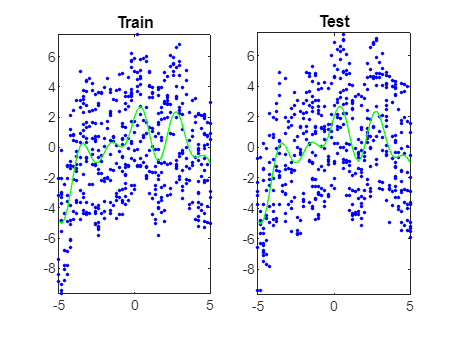

subplot(1,2,1)
hold on;
plot(xss, f_xss, '-g');
hold off

subplot(1,2,2)
hold on;
plot(xss_test, f_xss_test, '-g');
hold off

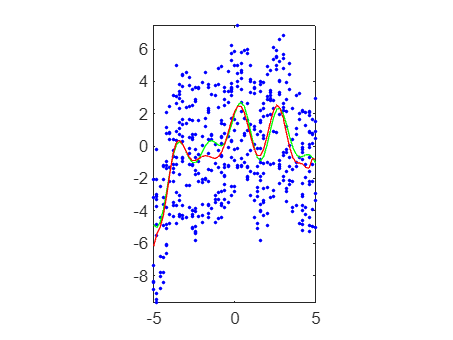

M = 16;

A = fliplr(vander(xss));
A = A(:,1:M);
A_test = fliplr(vander(xs_test));
A_test = A_test(:,1:M);

xhat = (A'*A)^-1*A'*yss;
yhat  = A*xhat;
yhat_test = A_test*xhat;

% or just: 
xhat = A\yss;

% MATLAB defaults to least square solution (usually)

fig2 = figure(2);
clf(fig2);
plot(xs, ys, '.b');
hold on;
plot(xss, f(xss), '-g');
plot(xss, yhat, "-r");
axis(lims);
daspect([1 1 1]);
hold off


error_train = 1/N*sum((yss - yhat).*(yss-yhat))

error_train = 7.9488

error_test = 1/N*sum((yss_test - yhat_test).*(yss_test-yhat_test))

error_test = 14.5818

real_error = 1/N*sum((f(xss) - yhat).*(f(xss) - yhat))

real_error = 0.1980

xhat

xhat =     2.1437
    2.4256
   -3.3818
   -2.7146
    1.4111
    1.0750
   -0.2519
   -0.1872
    0.0235
    0.0167


How about a more interesting set of basis functions, let's use $\{1, x, x^2, x^3, \sin(x), \cos(x), \sin(2 x),\cos(2x), \sin(3x), \cos(3x)\}$ as the set of basis functions..

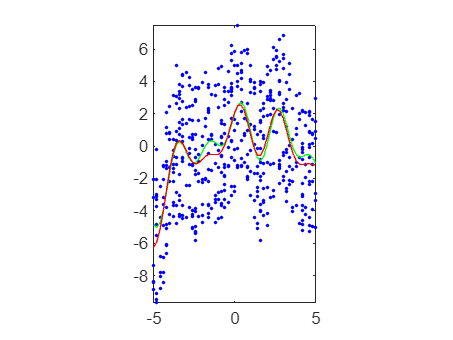

A = [xss.^0 xss.^1 xss.^2 xss.^3 ...
    sin(xss) cos(xss) sin(2*xss) cos(2*xss) sin(3*xss) cos(3*xss)];
A_test = [xs_test.^0 xs_test.^1 xs_test.^2 xs_test.^3 ...
    sin(xs_test) cos(xs_test) sin(2*xs_test) cos(2*xs_test) ...
    sin(3*xs_test) cos(3*xs_test)];

xhat = (A'*A)^-1*A'*yss;
yhat  = A*xhat;
yhat_test = A_test*xhat;

fig3 = figure(3);
clf(fig3);
plot(xss, yss, '.b')
hold on;
plot(xss, f(xss), '-g');
plot(xss, yhat, "-r");
axis(lims);
daspect([1 1 1]);
hold off


error_train = 1/N*sum((yss - yhat).*(yss-yhat))

error_train = 7.9602

error_test = 1/N*sum((yss_test - yhat_test).*(yss_test-yhat_test))

error_test = 14.5685

real_error = 1/N*sum((f(xss) - yhat).*(f(xss) - yhat))

real_error = 0.1542

xhat

xhat =     0.9238
   -0.0334
   -0.1415
    0.0223
    0.7293
   -0.1376
   -0.1528
    1.1339
    0.8100
    0.1722
